clc; clear; close all;
addpath('functions/');

n = 200;

x1 = 0;
v1 = 0;
t = 1; 

sigmaA = 0.2;
sigmaN = 20;
probability = 0.3;


M = 500;

G = [(t^2)/2; t];
F = ([1, t; 0, 1]);
F7 = F^6;
H = [1, 0];
Q = sigmaA^2 * (G*G');


ErrSum = zeros(1,n);
ErrSumextr = zeros(1,n);
ErrSumfiltr = zeros(1,n);
Pfiltr = zeros(1,n);
Pextr = zeros(1,n);
Xk = zeros(2, n);
Xkextr = zeros(2,n);
Xkfiltr = zeros(2,n);

aErrSum = zeros(1,n);
aErrSumextr = zeros(1,n);
aErrSumfiltr = zeros(1,n);
aPfiltr = zeros(1,n);
aPextr = zeros(1,n);
aXk = zeros(2, n);
aXkextr = zeros(2,n);
aXkfiltr = zeros(2,n);

bErrSum = zeros(1,n);
bErrSumextr = zeros(1,n);
bErrSumfiltr = zeros(1,n);
bPfiltr = zeros(1,n);
bPextr = zeros(1,n);
bXk = zeros(2, n);
bXkextr = zeros(2,n);
bXkfiltr = zeros(2,n);

cErrSum = zeros(1,n);
cErrSumextr = zeros(1,n);
cErrSumfiltr = zeros(1,n);
cPfiltr = zeros(1,n);
cPextr = zeros(1,n);
cXk = zeros(2, n);
cXkextr = zeros(2,n);
cXkfiltr = zeros(2,n);


for j=1:M
    Acc = normrnd(0, sigmaA, 1, n);
    Noise = normrnd(0,sigmaN,1,n);
    X = calcTrajectory11( Acc, x1, v1, t);
    Y = X + Noise;
      
    Z = Y;
    Z(rand(1,n) < probability) = NaN;
    
    Xk(:, 1) = [x1; v1];
    P = [10000, 0; 0, 10000];       
    
    for i=2:n
        if isnan(Z(i))
            Pfiltr(i)=P(1,1);
            Pextr(i)=P(1,1);
            Xk(:,i) = F*Xk(:, i-1);
            Xkextr(:,i)=Xk(:,i);
            Xkfiltr(:,i)=Xk(:,i);
        else    
            P = F*P*F'+Q;
            Pextr(i)=P(1,1);
            K = P*H'/(H*P*H' + sigmaN^2);
            Xk(:,i) = F*Xk(:, i-1);
            Xkextr(:,i)=Xk(:,i);
            Xk(:,i) = Xk(:,i) + K*(Z(i)-H*Xk(:,i));
            Xkfiltr(:,i)=Xk(:,i);            
            P = (eye(2)-K*H)*P; 
            Pfiltr(i)=P(1,1);
        end
    end

%     bXk(:, 1:7) = [x1; v1];
    for i =1:7
        bXk(:, i) = [x1; v1];
    end
    P = [10000, 0; 0, 10000];       
    
    for i=8:n
        if isnan(Z(i))
            bPfiltr(i)=P(1,1);
            bPextr(i)=P(1,1);
            bXk(:,i) = F7*bXk(:, i-7);
            bXkextr(:,i)=bXk(:,i);
            bXkfiltr(:,i)=bXk(:,i);
        else    
            P = F7*P*F7'+Q;
            bPextr(i)=P(1,1);
            K = P*H'/(H*P*H' + sigmaN^2);
            bXk(:,i) = F7*bXk(:, i-7);
            bXkextr(:,i)=bXk(:,i);
            bXk(:,i) = bXk(:,i) + K*(Z(i)-H*bXk(:,i));
            bXkfiltr(:,i)=bXk(:,i);            
            P = (eye(2)-K*H)*P; 
            bPfiltr(i)=P(1,1);
        end
    end

    
    aXk(:, 1) = [x1; v1];
    P = [10000, 0; 0, 10000];       
    
    for i=2:n    
        P = F*P*F' + Q;
        aPextr(i)=P(1,1);
        K = P*H'/(H*P*H' + sigmaN^2);
        aXk(:,i) = F*aXk(:, i-1);
        aXkextr(:,i)=aXk(:,i);
        aXk(:,i) = aXk(:,i) + K*(Y(i)-H*aXk(:,i));
        aXkfiltr(:,i)=aXk(:,i);            
        P = (eye(2)-K*H)*P; 
        aPfiltr(i)=P(1,1);
    end

    for i =1:7
        cXk(:, i) = [x1; v1];
    end
    P = [10000, 0; 0, 10000];       
    
    for i=8:n    
        P = F7*P*F7'+Q;
        cPextr(i)=P(1,1);
        K = P*H'/(H*P*H' + sigmaN^2);
        cXk(:,i) = F7*cXk(:, i-7);
        cXkextr(:,i)=cXk(:,i);
        cXk(:,i) = cXk(:,i) + K*(Y(i)-H*cXk(:,i));
        cXkfiltr(:,i)=cXk(:,i);            
        P = (eye(2)-K*H)*P; 
        cPfiltr(i)=P(1,1);
    end
    
    ErrCur1 = ( Xkextr(1,:) - X(1,:) ).^2;
    ErrSumextr = ErrSumextr + ErrCur1;
    ErrCur2 = ( Xkfiltr(1,:) - X(1,:) ).^2;
    ErrSumfiltr = ErrSumfiltr + ErrCur2;

    aErrCur1 = ( aXkextr(1,:) - X(1,:) ).^2;
    aErrSumextr = aErrSumextr + aErrCur1;
    aErrCur2 = ( aXkfiltr(1,:) - X(1,:) ).^2;
    aErrSumfiltr = aErrSumfiltr + aErrCur2;
    
    bErrCur1 = ( bXkextr(1,:) - X(1,:) ).^2;
    bErrSumextr = bErrSumextr + bErrCur1;
    bErrCur2 = ( bXkfiltr(1,:) - X(1,:) ).^2;
    bErrSumfiltr = bErrSumfiltr + bErrCur2;

    cErrCur1 = ( cXkextr(1,:) - X(1,:) ).^2;
    cErrSumextr = cErrSumextr + cErrCur1;
    cErrCur2 = ( cXkfiltr(1,:) - X(1,:) ).^2;
    cErrSumfiltr = cErrSumfiltr + cErrCur2;

end

FinalErrorextr = ( ErrSumextr(3:end)./(M-1) ).^0.5;
FinalErrorfiltr = ( ErrSumfiltr(3:end)./(M-1) ).^0.5;
aFinalErrorextr = ( aErrSumextr(3:end)./(M-1) ).^0.5;
aFinalErrorfiltr = ( aErrSumfiltr(3:end)./(M-1) ).^0.5;
bFinalErrorextr = ( bErrSumextr(3:end)./(M-1) ).^0.5;
bFinalErrorfiltr = ( bErrSumfiltr(3:end)./(M-1) ).^0.5;
cFinalErrorextr = ( cErrSumextr(3:end)./(M-1) ).^0.5;
cFinalErrorfiltr = ( cErrSumfiltr(3:end)./(M-1) ).^0.5;


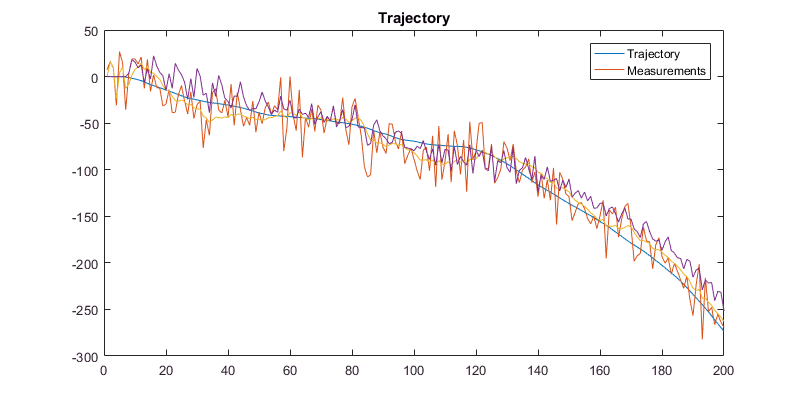

figure('position', [0, 0, 800, 400])
    plot(1:n, X, 1:n, Y, 1:n, aXk(1,:), 1:n, cXk(1,:));
    title('Trajectory')
    legend('Trajectory', 'Measurements');

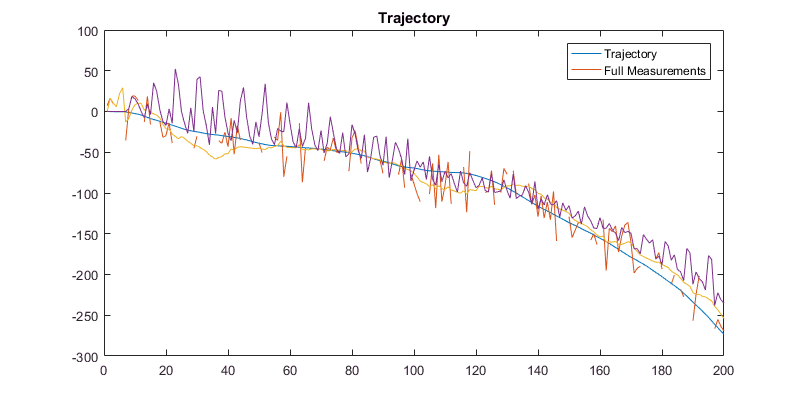

    
figure('position', [0, 0, 800, 400]);
    plot(1:n, X, 1:n, Z, 1:n, Xk(1,:), 1:n, bXk(1,:));
    title('Trajectory')
    legend('Trajectory', 'Full Measurements');  

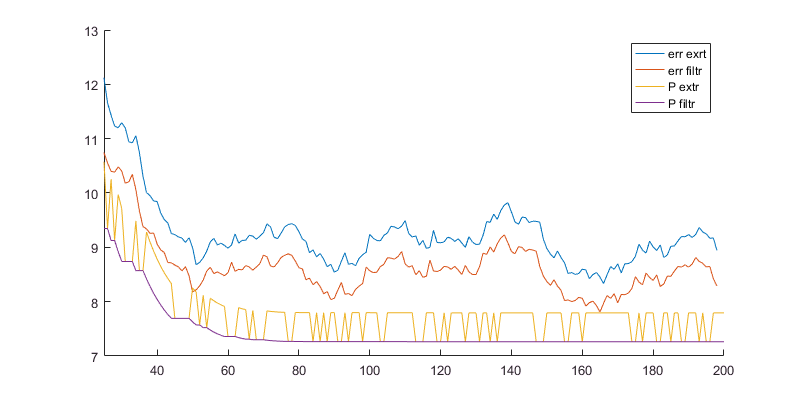

figure('position', [0, 0, 800, 400]); hold on
    plot(FinalErrorextr);
    plot(FinalErrorfiltr);
    plot(Pextr.^0.5);
    plot(Pfiltr.^0.5);
    xlim([25 200]);
    legend('err exrt', 'err filtr', 'P extr', 'P filtr');

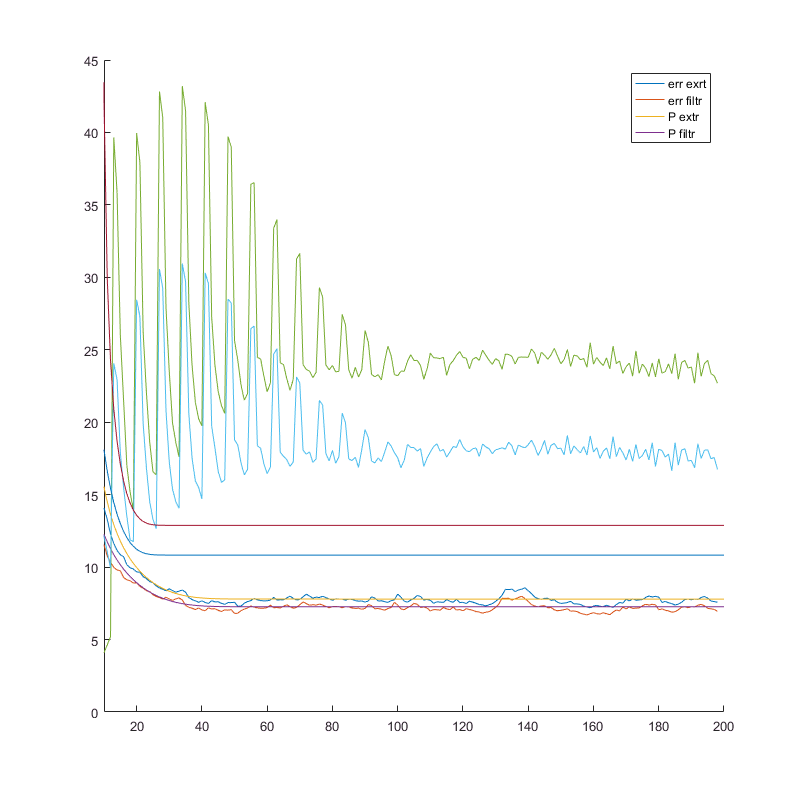

figure('position', [0, 0, 800, 800]); hold on;
    plot(aFinalErrorextr);
    plot(aFinalErrorfiltr);
    plot(aPextr.^0.5);
    plot(aPfiltr.^0.5);
    plot(cFinalErrorextr);
    plot(cFinalErrorfiltr);
    plot(cPextr.^0.5);
    plot(cPfiltr.^0.5);
    xlim([10 200]);
    legend('err exrt', 'err filtr', 'P extr', 'P filtr');

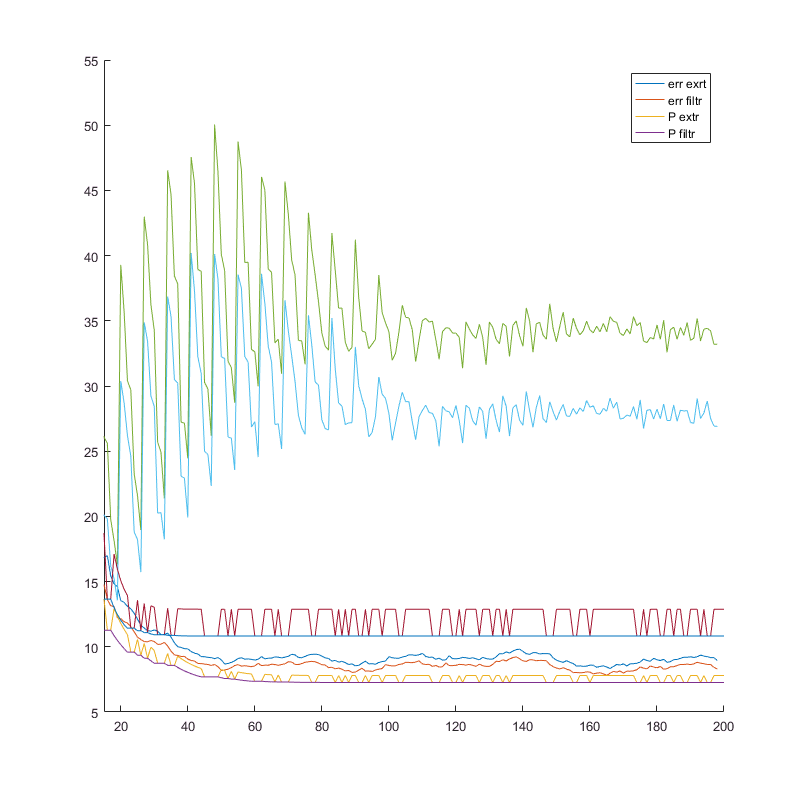

    
figure('position', [0, 0, 800, 800]); hold on
    plot(FinalErrorextr);
    plot(FinalErrorfiltr);
    plot(Pextr.^0.5);
    plot(Pfiltr.^0.5);
    plot(bFinalErrorextr);
    plot(bFinalErrorfiltr);
    plot(bPextr.^0.5);
    plot(bPfiltr.^0.5);
    xlim([15 200]);
    legend('err exrt', 'err filtr', 'P extr', 'P filtr');